## Open or consolidate data files

open the excel files with the test data to generate the database

clear
is_Mac = 0;
consolidate = 1;

if is_Mac
    save_path='/Users/tomasodeponti/Desktop/Flight data of VSQP/static_test_1805/database/general';
    data_path='/Users/tomasodeponti/Desktop/Flight data of VSQP/static_test_1805/database/single';
    addpath(genpath('/Users/tomasodeponti/Desktop/thesis/rot_wing_drone/sw')) %addpath(genpath('.\sw'))
else
    %save_path='C:\Users\Tomaso\Desktop\flight_data_VSQP\static_test_1805\database\general';
    %data_path='C:\Users\Tomaso\Desktop\flight_data_VSQP\static_test_1805\database\single';
    save_path='C:\Users\Tomaso\Desktop\flight_data_VSQP\static_test_1805\database\general';
    data_path='C:\Users\Tomaso\Desktop\flight_data_VSQP\static_test_1805\database\single';
    addpath(genpath('C:\Users\Tomaso\Desktop\Thesis\main\sw'))
end 
unit_header = ["ID","Item","Windspeed [m/s]","Airspeed [m/s]","Skew [deg]","Skew_sp [deg]","Mot_Status","Excitation","Mx [Nm]","My [Nm]","Mz [Nm]","Fx [N]","Fy[N]","Fz [N]","Mot_F [pwm]","Mot_R [pwm]","Mot_B [pwm]","Mot_L [pwm]","Ail_L [pwm]","Ail_R [pwm]","Elev [pwm]","Rud [pwm]","Pitch [deg]"];    
database_header = ["ID","Item","Windspeed","Airspeed","Skew","Skew_sp","Mot_Status","Excitation","Mx","My","Mz","Fx","Fy","Fz","Mot_F","Mot_R","Mot_B","Mot_L","Ail_L","Ail_R","Elev","Rud","Pitch"];
if consolidate
    xlsxFiles = dir(fullfile(data_path,'*.xlsx')); 
    numfiles = length(xlsxFiles);
    mydata = cell(1, numfiles);
    all    = [];
    for k = 1:numfiles 
      mydata{k} = xlsread(fullfile(data_path,xlsxFiles(k).name)); 
      all = [all;mydata{k}];
    end
    Table = array2table(all,'VariableNames',database_header);
    name = 'static_test_2.xlsx';
    table_path_format = fullfile(save_path,name);
    writetable(Table,table_path_format); 
else
    xlsxFiles = dir(fullfile(save_path,'*.xlsx'));
    all = xlsread(fullfile(save_path,xlsxFiles.name)); 
    Table = array2table(all,'VariableNames',database_header);
end


## Perform transformation from balance to drone c.g. and apply calibration

data = Table;

if is_Mac
    path = '/Users/tomasodeponti/Desktop/Flight data of VSQP/static_test_1605/OJF/calibration';
else
    path = 'C:\Users\Tomaso\Desktop\flight_data_VSQP\static_test_1605\OJF\calibration';
end
name = strcat('calibration.txt');
fid = fopen(fullfile(path,name));
format = sprintf('%s', repmat('%f', 1, 7));
calibration = cell2mat(textscan(fid, format,'Delimiter', ','));
fclose(fid);

for i =1:size(data,1)
    int_cal = interp1(calibration(:,1),calibration(:,2:end),data.Windspeed(i));
    data.Fx(i) = (data.Fx(i)-int_cal(1)).*(-1);
    data.Fy(i) = (data.Fy(i)-int_cal(2)).*(-1);
    data.Fz(i) = data.Fz(i)-int_cal(3);
    data.Mx(i) = (data.Mx(i)-int_cal(4)).*(-1);
    data.My(i) = (data.My(i)-int_cal(5)).*(-1);
    data.Mz(i) = data.Mz(i)-int_cal(6);
end

pole = [0,0,-1.2085].'; %[0,0,-1]90.5+5.5+8+16.85 -1.04
m_i  = [data.Mx,data.My,data.Mz];
f_i  = [data.Fx,data.Fy,data.Fz];
m_e  = m_i + cross(f_i,pole.'.*ones(size(f_i)));
data.Mx = m_e(:,1);
data.My = m_e(:,2);
data.Mz = m_e(:,3);
data2 = data;


## **Question to be answered**

*What is the CL curve of the drone at different pitch angles*

## Filter out not filled data points

data2 = data2(data2.Windspeed<16,:);
data2.Pitch = round(data2.Pitch);
data2.Skew_sp = max(data2.Skew_sp,0);
data2.Windspeed = round(data2.Windspeed);

## Investigate the lifting properties of the wing

folder = fullfile(pwd,'plots_save');
baseline = 0 ;
baseline = baseline+k;
pitches = unique(round(data2.Pitch));
v = unique(data2.Windspeed);
%v_sel = v(3);
leg_pitch = [];
for i=[3,5,8]
    leg_pitch= [leg_pitch,strcat(string(i),'[deg]'),''];
end
visible = 0;
save_pictures = 1;
for m=v(1:3).'
    if visible
      f=figure(baseline+k+1);
    else
      f=figure('visible','off');
    end
    clf
    cla
    t = tiledlayout(2,3);
    for j=9:14
        if  j==14
            order = 11; %11
        elseif j==9
            order = -1;
        else 
            order = 1;
        end
        nexttile
        hold on
        [tf, loc] = ismember([3,5,8],pitches);
        for i=loc
            out  = table_sifter(data2,[-1,5,m,-1,-1,-1,0,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,pitches(i)]);
            temp = plot_special(out.(6),out.(j),order,i);
        end
        if j <12
            ylim([-7 6])
        else
            ylim([-50 2])
        end
        xlabel(unit_header(5))
        ylabel(unit_header(j))
        grid on
        grid minor
        hold off
    end
    lgd = legend(leg_pitch,'NumColumns',4);
    lgd.Layout.Tile = 'north';
    title(t,strcat('Lifting properties Wing at different pitch angles'," ",num2str(m),' [m/s]'," fixed test" ))
    tit2 = strcat("Wing_pitch_study_v_",num2str(m),'_fixed_test');
    hold off
    if save_pictures
        saveas(f,fullfile(folder,strcat(tit2,'.jpg')))
    end
end

lsqr stopped at iteration 50 without converging to the desired tolerance 1e-12
because the maximum number of iterations was reached.
The iterate returned (number 50) has relative residual NaN.
lsqr stopped at iteration 50 without converging to the desired tolerance 1e-12
because the maximum number of iterations was reached.
The iterate returned (number 50) has relative residual NaN.
lsqr converged at iteration 1 to a solution with relative residual 0.94.
lsqr converged at iteration 1 to a solution with relative residual 0.79.
lsqr converged at iteration 1 to a solution with relative residual 0.75.
lsqr converged at iteration 1 to a solution with relative residual 0.63.
lsqr converged at iteration 1 to a solution with relative residual 0.96.
lsqr stopped at iteration 50 without converging to the desired tolerance 1e-12
because the maximum number of iterations was reached.
The iterate returned (number 50) has relative residual NaN.
lsqr converged at iteration 1 to a solution with relativ

Investigate CL curve

pitches = unique(round(data2.Pitch));
v = unique(data2.Windspeed);
leg_skew = [];
skews_sp = unique(data2.Skew_sp);
skews_sp(1) = 0;
L = 0.5 * 1.225 * 1.56 * 0.235 ;
visible = 0;
save_pictures = 1;
if visible
  f=figure(20);
else
  f=figure('visible','off');
end
t = tiledlayout(1,1);
clf
cla
nexttile
hold on
for i=1:max(size(skews_sp))
    leg_skew= [leg_skew,strcat(string(skews_sp(i)),'[deg]'),''];
    out  = table_sifter(data2,[-1,5,-1,-1,-1,skews_sp(i),0,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1]);
    CL   = -1.*out.Fz./(L*out.Windspeed.^2);
    temp = plot_special(out.Pitch,CL,-1,i);
end

lsqr converged at iteration 1 to a solution with relative residual 0.17.
lsqr converged at iteration 1 to a solution with relative residual 0.22.
lsqr converged at iteration 1 to a solution with relative residual 0.25.
lsqr converged at iteration 1 to a solution with relative residual 0.3.
lsqr converged at iteration 1 to a solution with relative residual 0.34.
lsqr converged at iteration 1 to a solution with relative residual 0.35.
lsqr converged at iteration 1 to a solution with relative residual 0.35.


xlabel(unit_header(end))
ylabel("C_L [-]")
grid on
grid minor
% leg_skew = [leg_skew,"XFLR Prediction"];
% angles = [0,1,2,3,4,5,6,7,8,9,10,11,12,13];
% cl = [0.0723,0.167,0.262,0.357,0.451,0.546,0.640,0.733,0.826,0.918,1.009,1.100,1.190,1.279];
% plot(angles,cl)
hold off 
lgd = legend(leg_skew,'NumColumns',4);
lgd.Layout.Tile = 'north';
title("C_L curve at different skew angles fixed test")
tit2 = strcat("Wing_CL_curve",'_fixed_test');
if save_pictures
    saveas(f,fullfile(folder,strcat(tit2,'.jpg')))
end

## Investigate motor effect

lsqr converged at iteration 4 to a solution with relative residual 0.85.
lsqr converged at iteration 8 to a solution with relative residual 0.3.
lsqr converged at iteration 12 to a solution with relative residual 0.14.
lsqr converged at iteration 19 to a solution with relative residual 0.14.
lsqr converged at iteration 30 to a solution with relative residual 0.11.
lsqr converged at iteration 1 to a solution with relative residual 1.
lsqr converged at iteration 1 to a solution with relative residual 1.
lsqr converged at iteration 1 to a solution with relative residual 0.99.
lsqr converged at iteration 2 to a solution with relative residual 0.98.
lsqr converged at iteration 2 to a solution with relative residual 0.98.
lsqr converged at iteration 3 to a solution with relative residual 0.96.
lsqr converged at iteration 2 to a solution with relative residual 0.85.
lsqr converged at iteration 2 to a solution with relative residual 0.85.
lsqr converged at iteration 2 to a solution with relati

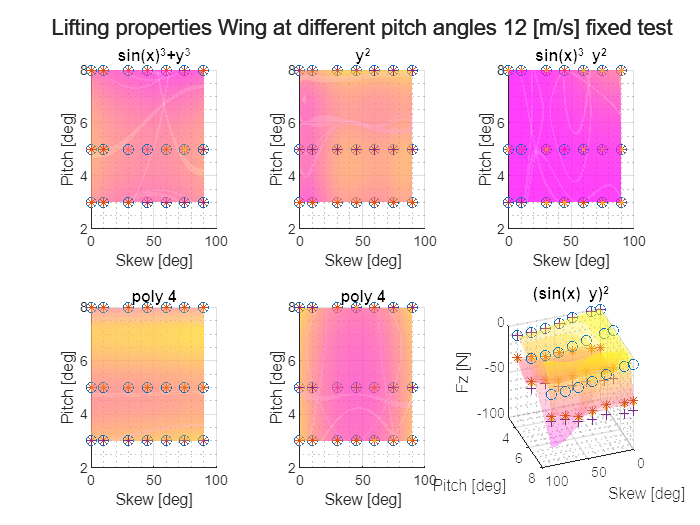

visible = 1;
save_pictures = 0;
for m=v(3).'
    if visible
      f=figure(100);
    else
      f=figure('visible','off');
    end
    clf
    cla
    t = tiledlayout(2,3);
    for j=9:14
        if  j==14
            order = 11; %11
        elseif j==9
            order = -1;
        else 
            order = 1;
        end
        nexttile
        hold on
%         [tf, loc] = ismember([3,5,8],pitches);
%         for i=loc
            for o=[0,1,2,3]
                out  = table_sifter(data2,[-1,5,m,-1,-1,-1,o,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1,-1]);
                temp = plot3_special(out.(6),out.(23),out.(j),1,o+1);
            end
%         end
%         if j <12
%             ylim([-7 6])
%         else
%             ylim([-50 2])
%         end
        xlabel(unit_header(5))
        ylabel(unit_header(23))
        zlabel(unit_header(j))
        grid on
        grid minor
        hold off
    end
%     lgd = legend(leg_pitch,'NumColumns',4);
%     lgd.Layout.Tile = 'north';
    title(t,strcat('Lifting properties Wing at different pitch angles'," ",num2str(m),' [m/s]'," fixed test" ))
    tit2 = strcat("Wing_pitch_study_v_",num2str(m),'_fixed_test');
    hold off
    view([160 30])
    if save_pictures
        saveas(f,fullfile(folder,strcat(tit2,'.jpg')))
    end
end